# Task 1.

#### Load the image

original  = imread("../left.jpg");

#### Show the image before passing it to the corner detector

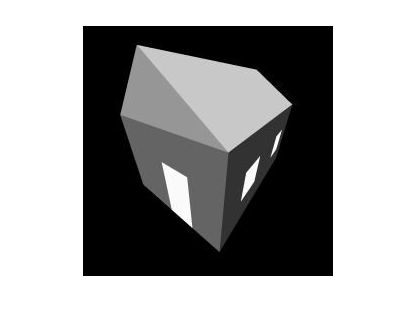

imshow(original);

% The threashold multiplier for the harris corner detector, a more
% contrasty image will need a higher th value
th = 100;

#### Passing the image to the corner detector

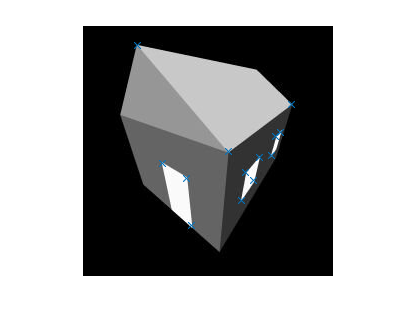

points = harris_corners(original,th);
img = original;
imshow(img);
hold on
scatter(points(:,2),points(:,1),'x');
hold off

figure

#### Rotating the image and repeating the procedure

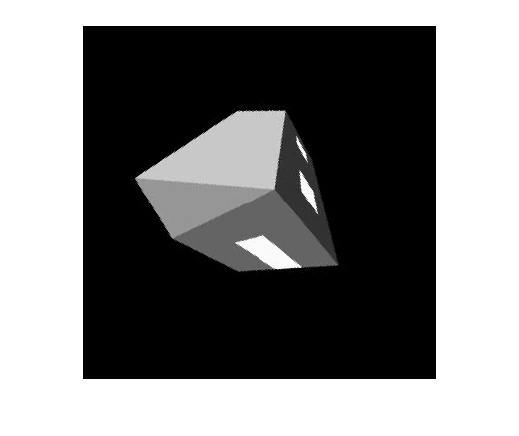

img_rot = imrotate(original,45);
imshow(img_rot);

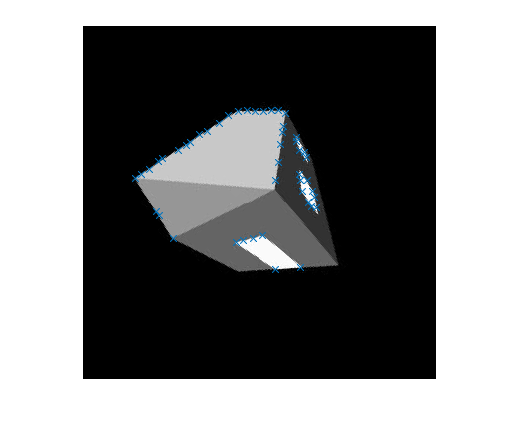

points = harris_corners(img_rot,th);
imshow(img_rot);
hold on
scatter(points(:,2),points(:,1),'x');
hold off

figure

The corners detected seem to be the same. But it seems to find some new corners also. These are likely artifacts from the rotation of the image. But most of the conrners detected in the non rotaded image are detected, hinting at rotation invariance.

#### Scaling the image down and repreating the procedure

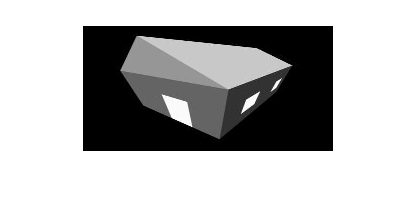

img_small = downsample(original,2);
imshow(img_small);

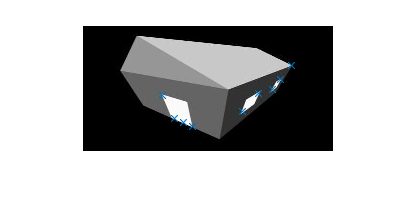

points = harris_corners(img_small,th);
imshow(img_small);
hold on
scatter(points(:,2),points(:,1),'x');
hold off

figure

It seems to find the same points but fewer when the image is downsampled. It finds more actual corners and fewer points along lines.

Scaling down to 4x

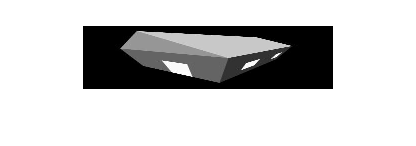

img_smaller = downsample(original,4);
imshow(img_smaller);

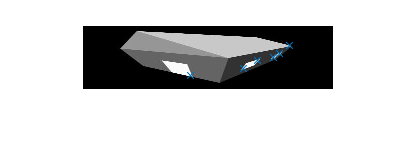

points = harris_corners(img_smaller,th);
imshow(img_smaller);
hold on
scatter(points(:,2),points(:,1),'x');
hold off

figure

Misses out on some corners, like the top edge of the house that the 2x downsample finds, this points to non scale invariance, which is logical since it's kernel based.

## Comparing my implementation to the matlab built in function

#### Using the matlab implementation

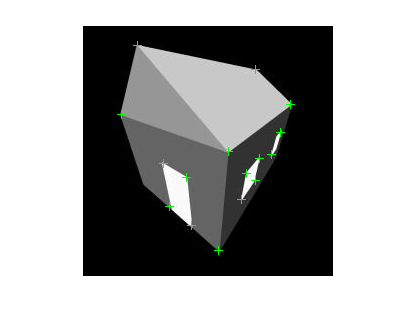

harris_left = detectHarrisFeatures(original);
imshow(original)
hold on
plot(harris_left);
hold off

figure

#### Using my implementation

points = harris_corners(original,th);
imshow(original);
hold on
scatter(points(:,2),points(:,1),'x');
hold off

figure

We can see that the built in implementation generates less false positives, I think that this is due to better calibration. In general they are quite similar, but the implementation done by matlab is much more complex syntax wise. 

## Parameter sellection

Making the thresholding value larger decreases the number of points detected as it should. I selected 100* the mean, which is quite resonable for the range of values in the harris matrix and it also removed most non relevant points from the image.

It also seems like a larger non maxima supperssion kernel is better for finding corners, but that also increases the computation time per frame.

## Harris corner detector implementation

Here is a coppy of the harris corner detector implemented in the harris_corner.m file

function points = harris_corners_copy(img,thresh)
% Computes corners in a provided image [img], thresholding with the value specified in thresh
%
% Returns an array of points where each point represens a corner
% A corner is represented with a vector [x,y,confidence,Ix,Iy]

       % Create the two filters, index 1 is horisontal gradient
       % index 2 is vertical gradient
       gray = im2double(im2gray(img));
       dx = [ -1 0 1];
       dy = dx';
       % Compute gradiants
       gradx = imfilter(gray,dx,'replicate','conv');
       grady = imfilter(gray,dy,'replicate','conv');
       
       % Greatly improves performance
       gauss = fspecial("gaussian",3,.5);

       gradxx = imfilter(gradx.^2,gauss);
       gradyy = imfilter(grady.^2,gauss);
       gradxy = imfilter(gradx.*grady,gauss);
       
       % Create temporary array to hold the lambda1 value
       harris = zeros(size(gray));
       for i = 1:size(gray,1)
           for j = 1:size(gray,2)
                H = [
                        gradxx(i,j) gradxy(i,j);
                        gradxy(i,j) gradyy(i,j)
                    ];
                lambda1 = det(H) / trace(H);
                if trace(H) ~= 0
                    harris(i,j) = abs(lambda1);
                end
           end
       end

       % get mean R before the non maxima suppression
       meanval = mean(mean(harris));
       % The threashold value is decided by a multiple of the mean val and
       % a user provided thresh value
       threshold = meanval*thresh;
       % Holding variable, this will change size on every itteration, since
       % matlab has no good dpp support this is the way it has to be. And I
       % can't pre allocate without risking memory waste
       points = [];

       % size of non max kernel
       n = 7;
       n = floor(n/2);
       % non maxima suppression
       for i = 1+n:size(harris,1)-n
           for j = 1+n:size(harris,2)-n
                v = harris(i,j);
                % Threshold the image
                if v < threshold
                    continue
                end
                % assume it's a max
                max = 1;
                for k = -n:n
                    for l = -n:n
                        if v < harris(i+k,j+l)
                            max = 0;
                        end
                    end
                end
                
                if max
                    points = [points;[i,j,v,gradx(i,j),grady(i,j)]];
                end
           end
       end
end